R_squared = 0.9984

R_squared = 0.9117

R_squared = 0.9915

R_squared = 0.8555

R_squared = 0.9982

R_squared = 0.9937

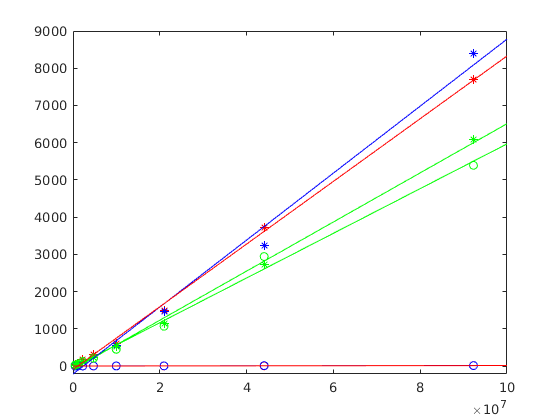

R_squared = 0.9044

R_squared = 0.8700

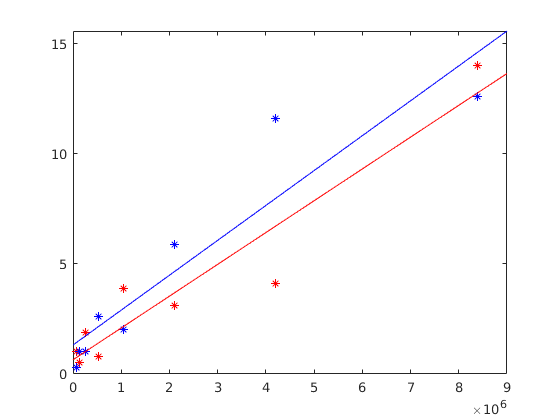

filename1 = '/home/jeremydohmann/Documents/hdd/home/Documents/Thesis/appendix/code/btreefiltering/full_tree/terminal_tree_filter_stats.csv';
filename2 = '/home/jeremydohmann/Documents/hdd/home/Documents/Thesis/appendix/code/btreefiltering/full_tree/terminating_tree_stats.csv';
filename3 = '/home/jeremydohmann/Documents/hdd/home/Documents/Thesis/appendix/code/btreefiltering/full_tree/basic_filter_stats.csv';
run_results(filename1, filename2, filename3)

function run_results(file1, file2, file3)
    M = csvread(file1, 1, 0);
    g1 = M(:,1);
    t1 = M(:,2);
    p1 = M(:,3);
    worst1 = M(:,4);
    worst_len1 = M(:,5);
    median1 = M(:,6);
    median_len1 = M(:,7);
    
    M = csvread(file2, 1, 0);
    g2 = M(:,1);
    t2 = M(:,2);
    p2 = M(:,3);
    worst2 = M(:,4);
    worst_len2 = M(:,5);
    median2 = M(:,6);
    median_len2 = M(:,7);
    
    M = csvread(file3, 1, 0);
    g3 = M(:,1);
    t3 = M(:,2);
    p3 = M(:,3);
    worst3 = M(:,4);
    worst_len3 = M(:,5);
    median3 = M(:,6);
    median_len3 = M(:,7);
    % plot_results(p .* t,worst, median)
    plot_results(g1,g2, g3, worst1, median1, worst2, median2, worst3, median3)
    plot_results2(p1, p2, median1, median2)
end

function plot_results(x1, x2, x3, y1, y2, y3, y4, y5, y6)
    rng default;  % For reproducibility
    figure;

    plot(x1,y1,'r*')
    hold on

    plot(x1,y2,'ro')
    
    plot(x2,y3,'b*')
    hold on

    plot(x2,y4,'bo')
    
    plot(x3,y5,'g*')
    hold on

    plot(x3,y6,'go')
    
    R=corrcoef(x1,y1);
    R_squared=R(2)^2
    
    R=corrcoef(x1,y2);
    R_squared=R(2)^2
    
    R=corrcoef(x2,y3);
    R_squared=R(2)^2
    
    R=corrcoef(x2,y4);
    R_squared=R(2)^2
    
    R=corrcoef(x3,y5);
    R_squared=R(2)^2
    
    R=corrcoef(x3,y6);
    R_squared=R(2)^2
    lsline
end

function plot_results2(x1, x2, y1, y2)
    rng default;  % For reproducibility
    figure;

    plot(x1,y1,'r*')
    hold on

    plot(x2,y2,'b*')
    


    R=corrcoef(x1,y1);
    R_squared=R(2)^2
    
    R=corrcoef(x2,y2);
    R_squared=R(2)^2

    lsline
end
